## 数据导入-贵州省

filename = 'D:\Drivers\CarbonEmissiondata\Guizhou_data.xlsx'; 
dataTable = readtable(filename);
%years = data.Year;  

% 对二氧化碳排放量进行插值CarbonEmissions_mt 缺少2019年的碳排放，使用三次样条计算后得到331.31
%carbonEmissionsIndex = ~ismissing(data.CarbonEmissions_mt); 
%data.CarbonEmissions_mt(carbonEmissionsIndex == 0) = interp1(years(carbonEmissionsIndex), data.CarbonEmissions_mt(carbonEmissionsIndex), years(carbonEmissionsIndex == 0), 'spline');

dataGDP_ren = dataTable.Per_capita_GDP_yuan(1:25);
dataGDP = dataGDP_ren.';

dataPopulation_wan = dataTable.Population_wan(1:25);
dataPopulation = dataPopulation_wan.';
disp(dataPopulation)

   1.0e+03 *

    3.6353    3.6758    3.7163    3.7560    3.7990    3.8370    3.8700    3.9040    3.7300    3.6900    3.6320    3.5960    3.5370    3.4790    3.5300    3.5870    3.6320    3.6770    3.7080    3.7580    3.8030    3.8220    3.8480    3.8580    3.8520



dataSecond_billion = dataTable.Value_added_of_the_secondary_industry_billion(1:25);
dataSecond = dataSecond_billion.';

dataCE_mt = dataTable.CarbonEmissions_mt(1:25);
%dataCE = dataCE_mt.';

dataCoal_tons = dataTable.Coal_consumption_10000_tons(1:25);
dataCoke_tons = dataTable.Coke_consumption_10000_tons(1:25);
dataFuel_tons = dataTable.Fuel_oil_consumption_10000_tons(1:25);
energyconsumption= (dataCoal_tons+dataCoke_tons+dataFuel_tons);
dataEnergy = energyconsumption.';
disp(dataEnergy)

   1.0e+04 *

    0.5418    0.5741    0.5265    0.5385    0.5171    0.5433    0.7034    0.8263    0.8985    1.0416    1.1116    1.0183    1.1280    1.1289    1.2488    1.3710    1.4074    1.3493    1.3144    1.3896    1.3625    1.2218    1.2428    1.1560    1.0962




dataNatural_meters = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25);
dataNaturalgas = dataNatural_meters.';

dataTechnology_million = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25);
dataTechnology = dataTechnology_million.';

%dataFirepower_kilowatt= dataTable.Thermal_power_generation_100_million_kilowatt_hours(1:26);
%dataFire = dataFirepower_kilowatt.';

dataWaterpower_kilowatt= dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25);
%dataWater = dataWaterpower_kilowatt.';

dataTotalpower_kilowatt= dataTable.Total_power_generation_100_million_kilowatt_hours(1:25);
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_2=(dataWaterpower_kilowatt/dataTotalpower_kilowatt);
%dataWaterpercent=dataWaterpercent_2.';


## 人均GDP的LSTM模型

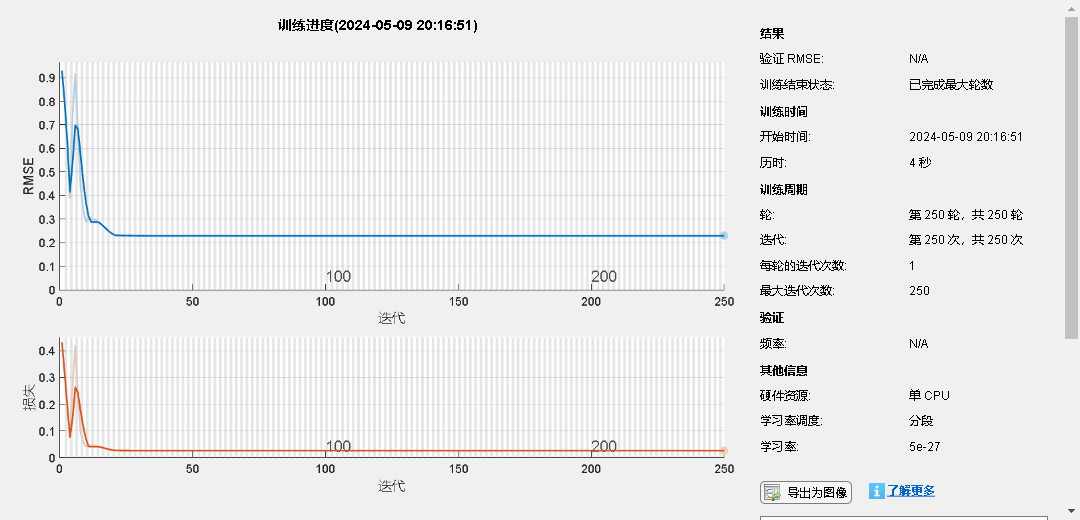

numTimeStepsTrain = numel(dataGDP); 
dataTrainGDP = dataGDP(1 : numTimeStepsTrain);
% 数据标准化，零均值和单位方差
muGDP = mean(dataTrainGDP);
sigGDP = std(dataTrainGDP);
dataTrainStandardizedGDP = (dataTrainGDP - muGDP) / sigGDP;
% 训练数据
XTrainGDP = dataTrainStandardizedGDP(1:end-1);
YTrainGDP = dataTrainStandardizedGDP(2:end);
% 创建 LSTM 网络
numFeaturesGDP = 1;
numResponsesGDP = 1;
numHiddenUnitsGDP = 100;

layersGDP = [sequenceInputLayer(numFeaturesGDP)
          lstmLayer(numHiddenUnitsGDP)
          fullyConnectedLayer(numResponsesGDP)
          regressionLayer];

% 设置网络参数
optionsGDP = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netGDP = trainNetwork(XTrainGDP, YTrainGDP, layersGDP, optionsGDP);

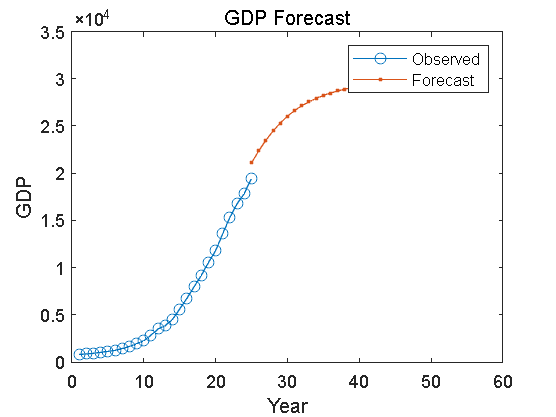

% 预测
netGDP = predictAndUpdateState(netGDP, XTrainGDP);
% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netGDP, YPredGDP] = predictAndUpdateState(netGDP, YTrainGDP(end));

% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictGDP = 28;
YPredGDP = [YPredGDP zeros(1, numYearsToPredictGDP - 1)]; % 预分配预测数组
for i = 2:numYearsToPredictGDP
    [netGDP, YPredGDP(:, i)] = predictAndUpdateState(netGDP, YPredGDP(:, i-1), 'ExecutionEnvironment', 'cpu');
end
% 去标准化
YPredGDP = sigGDP * YPredGDP + muGDP;
% 画图
figure;
plot(1:numel(dataGDP), dataGDP, '-o')
hold on
idx = numel(dataGDP) : (numel(dataGDP) + numYearsToPredictGDP - 1);
plot(idx, YPredGDP, '.-')
hold off 
xlabel("Year");
ylabel("GDP");
title("GDP Forecast");
legend("Observed", "Forecast");

%writematrix(YPred, 'D:\Drivers\LSTM_liaoningCEdata.xlsx'); % 修改为实际文件路径
disp(YPredGDP)

   1.0e+04 *

    2.1092    2.2359    2.3487    2.4470    2.5313    2.6029    2.6632    2.7140    2.7567    2.7926    2.8231    2.8489    2.8709    2.8898    2.9060    2.9201    2.9323    2.9430    2.9523    2.9605    2.9678    2.9742    2.9799    2.9850    2.9895    2.9936    2.9972    3.0004



## 人口的LSTM模型

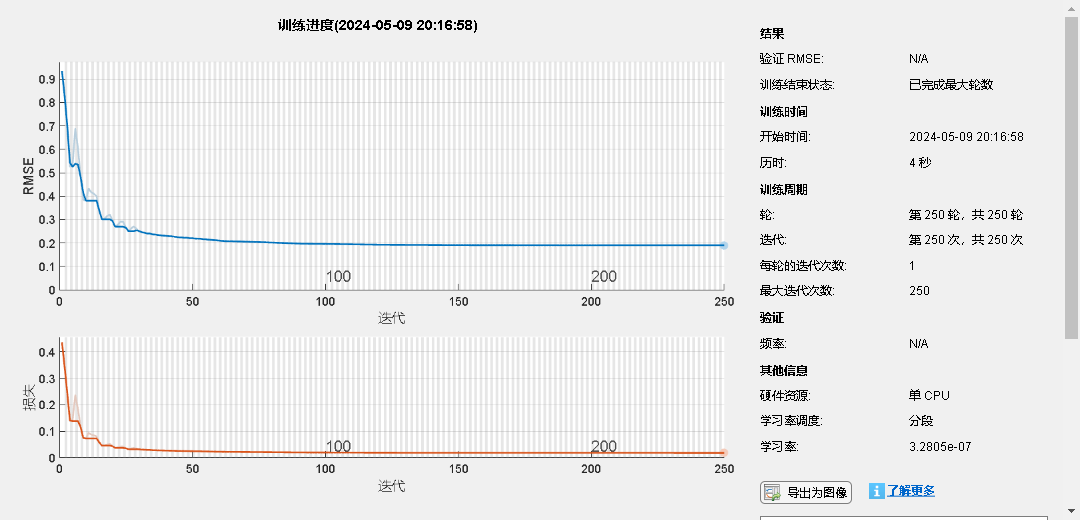

numTimeStepsTrainPopulation = numel(dataPopulation); % 使用所有的数据来训练
dataTrainPopulation = dataPopulation(1 : numTimeStepsTrainPopulation);

% 数据标准化，零均值和单位方差
muPopulation = mean(dataTrainPopulation);
sigPopulation = std(dataTrainPopulation);
dataTrainStandardizedPopulation = (dataTrainPopulation - muPopulation) / sigPopulation;

% 训练数据
XTrainPopulation = dataTrainStandardizedPopulation(1:end-1);
YTrainPopulation = dataTrainStandardizedPopulation(2:end);

% 创建 LSTM 网络
numFeaturesPopulation = 1;
numResponsesPopulation = 1;
numHiddenUnitsPopulation = 120;

layersPopulation = [sequenceInputLayer(numFeaturesPopulation)
          lstmLayer(numHiddenUnitsPopulation)
          fullyConnectedLayer(numResponsesPopulation)
          regressionLayer];

% 设置网络参数
optionsPopulation = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 30, ...
    'LearnRateDropFactor', 0.3, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netPopulation = trainNetwork(XTrainPopulation, YTrainPopulation, layersPopulation, optionsPopulation);

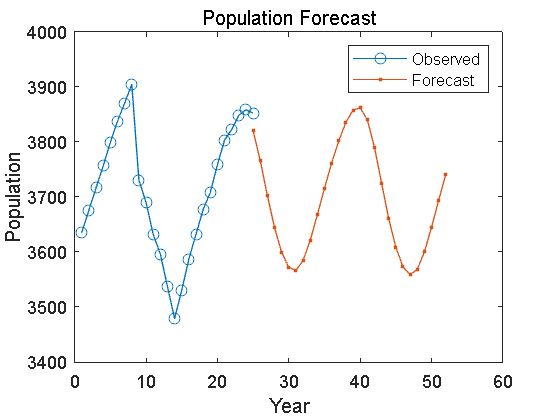


% 预测
netPopulation = predictAndUpdateState(netPopulation, XTrainPopulation);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netPopulation, YPredPopulation] = predictAndUpdateState(netPopulation, YTrainPopulation(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictPopulation = 28;
YPredPopulation = [YPredPopulation zeros(1, numYearsToPredictPopulation - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictPopulation
    [netPopulation, YPredPopulation(:, i)] = predictAndUpdateState(netPopulation, YPredPopulation(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredPopulation = sigPopulation * YPredPopulation + muPopulation;
% 画图
figure;
plot(1:numel(dataPopulation), dataPopulation, '-o')
hold on
idx = numel(dataPopulation) : (numel(dataPopulation) + numYearsToPredictPopulation - 1);
plot(idx, YPredPopulation, '.-')
hold off 
xlabel("Year");
ylabel("Population");
title("Population Forecast");
legend("Observed", "Forecast");

disp(YPredPopulation)

   1.0e+03 *

    3.8200    3.7657    3.7023    3.6442    3.5992    3.5718    3.5664    3.5843    3.6209    3.6673    3.7156    3.7611    3.8015    3.8349    3.8573    3.8617    3.8398    3.7902    3.7244    3.6603    3.6082    3.5728    3.5585    3.5684    3.5999    3.6448    3.6938    3.7410



## 第二产业的LSTM模型

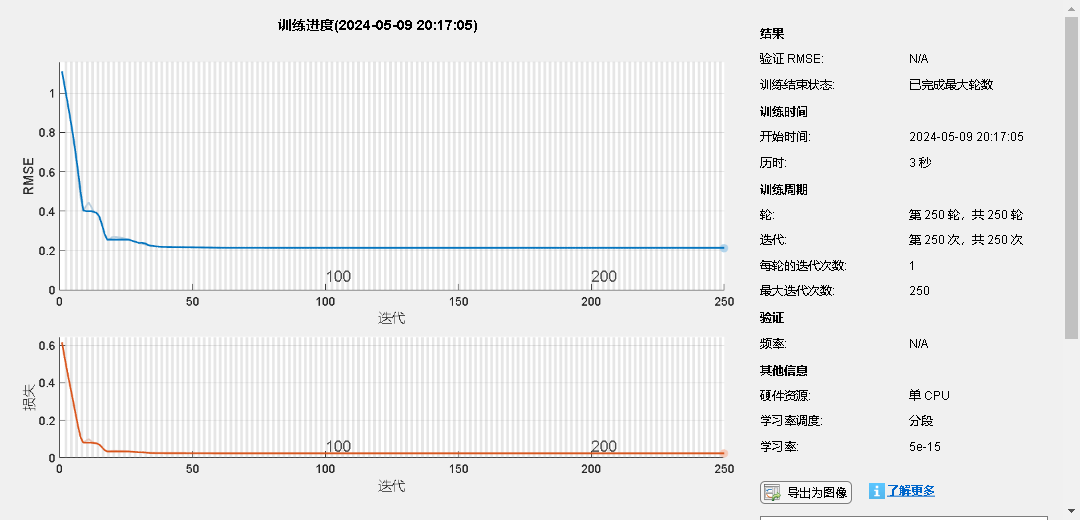

numTimeStepsTrainSecond = numel(dataSecond); 
dataTrainSecond = dataSecond(1 : numTimeStepsTrainSecond);

% 数据标准化，零均值和单位方差
musecond = mean(dataTrainSecond);
sigsecond = std(dataTrainSecond);
dataTrainStandardizedSecond = (dataTrainSecond - musecond) / sigsecond;

% 训练数据
XTrainSecond = dataTrainStandardizedSecond(1:end-1);
YTrainSecond = dataTrainStandardizedSecond(2:end);

% 创建 LSTM 网络
numFeaturesSecond= 1;
numResponsesSecond = 1;
numHiddenUnitsSecond = 40;

layersSecond = [sequenceInputLayer(numFeaturesSecond)
          lstmLayer(numHiddenUnitsSecond)
          fullyConnectedLayer(numResponsesSecond)
          regressionLayer];

% 设置网络参数
optionsSecond = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netSecond = trainNetwork(XTrainSecond, YTrainSecond, layersSecond, optionsSecond);

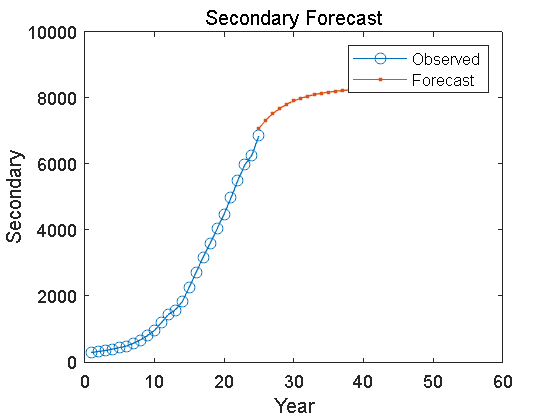


% 预测
netSecond = predictAndUpdateState(netSecond, XTrainSecond);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netSecond, YPredSecond] = predictAndUpdateState(netSecond, YTrainSecond(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictSecond = 28;
YPredSecond = [YPredSecond zeros(1, numYearsToPredictSecond - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictSecond
    [netSecond, YPredSecond(:, i)] = predictAndUpdateState(netSecond, YPredSecond(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredSecond = sigsecond * YPredSecond + musecond;
% 画图
figure;
plot(1:numel(dataSecond), dataSecond, '-o')
hold on
idx = numel(dataSecond) : (numel(dataSecond) + numYearsToPredictSecond - 1);
plot(idx, YPredSecond, '.-')
hold off 
xlabel("Year");
ylabel("Secondary");
title("Secondary Forecast");
legend("Observed", "Forecast");

disp(YPredSecond)

   1.0e+03 *

    7.0707    7.3182    7.5164    7.6748    7.8008    7.9007    7.9801    8.0433    8.0938    8.1343    8.1669    8.1934    8.2149    8.2326    8.2470    8.2590    8.2689    8.2771    8.2840    8.2897    8.2946    8.2987    8.3021    8.3051    8.3076    8.3097    8.3115    8.3131



## 煤炭等化石能源消耗量的LSTM模型

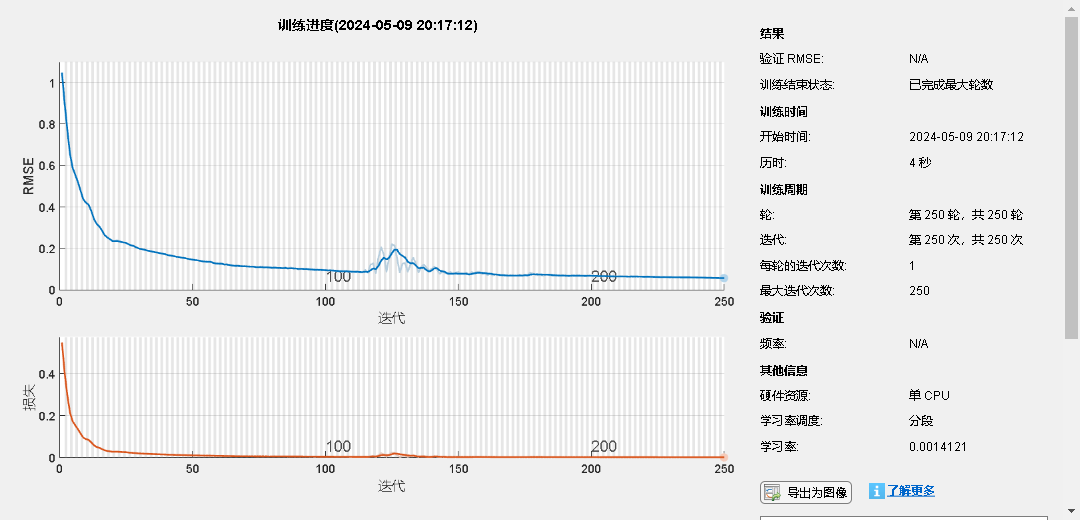

numTimeStepsTrainEnergy = numel(dataEnergy); 
dataTrainEnergy = dataEnergy(1 : numTimeStepsTrainEnergy);

% 数据标准化，零均值和单位方差
muEnergy = mean(dataTrainEnergy);
sigEnergy = std(dataTrainEnergy);
dataTrainStandardizedEnergy = (dataTrainEnergy - muEnergy) / sigEnergy;

% 训练数据
XTrainEnergy = dataTrainStandardizedEnergy(1:end-1);
YTrainEnergy = dataTrainStandardizedEnergy(2:end);

% 创建 LSTM 网络
numFeaturesEnergy= 1;
numResponsesEnergy = 1;
numHiddenUnitsEnergy = 100;

layersEnergy = [sequenceInputLayer(numFeaturesEnergy)
          lstmLayer(numHiddenUnitsEnergy)
          fullyConnectedLayer(numResponsesEnergy)
          regressionLayer];

% 设置网络参数
optionsEnergy = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.9, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同化石能源消耗背景下，改这个就行LearnRateDropFactor'
% 训练
netEnergy = trainNetwork(XTrainEnergy, YTrainEnergy, layersEnergy, optionsEnergy);

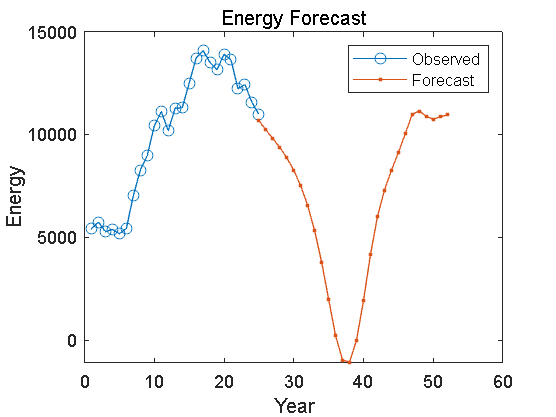


% 预测
netEnergy = predictAndUpdateState(netEnergy, XTrainEnergy);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netEnergy, YPredEnergy] = predictAndUpdateState(netEnergy, YTrainEnergy(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictEnergy = 28;
YPredEnergy = [YPredEnergy zeros(1, numYearsToPredictEnergy - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictEnergy
    [netEnergy, YPredEnergy(:, i)] = predictAndUpdateState(netEnergy, YPredEnergy(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredEnergy = sigEnergy * YPredEnergy + muEnergy;
% 画图
figure;
plot(1:numel(dataEnergy), dataEnergy, '-o')
hold on
idx = numel(dataEnergy) : (numel(dataEnergy) + numYearsToPredictEnergy - 1);
plot(idx, YPredEnergy, '.-')
hold off 
xlabel("Year");
ylabel("Energy");
title("Energy Forecast");
legend("Observed", "Forecast");

disp(YPredEnergy)

   1.0e+04 *

    1.0669    1.0218    0.9798    0.9367    0.8867    0.8261    0.7504    0.6543    0.5319    0.3793    0.1999    0.0218   -0.0967   -0.1065   -0.0006    0.1918    0.4147    0.5998    0.7275    0.8254    0.9114    1.0036    1.0986    1.1137    1.0881    1.0736    1.0854    1.0945



## 天然气的LSTM模型

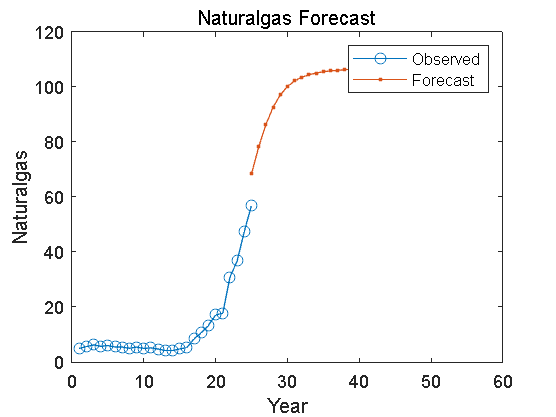

numTimeStepsTrainNaturalgas = numel(dataNaturalgas);
dataTrainNaturalgas = dataNaturalgas(1 : numTimeStepsTrainNaturalgas);

% 数据标准化，零均值和单位方差
muNaturalgas = mean(dataTrainNaturalgas);
sigNaturalgas = std(dataTrainNaturalgas);
dataTrainStandardizedNaturalgas = (dataTrainNaturalgas - muNaturalgas) / sigNaturalgas;

% 训练数据
XTrainNaturalgas = dataTrainStandardizedNaturalgas(1:end-1);
YTrainNaturalgas = dataTrainStandardizedNaturalgas(2:end);

% 创建 LSTM 网络
numFeaturesNaturalgas= 1;
numResponsesNaturalgas = 1;
numHiddenUnitsNaturalgas = 100;

layersNaturalgas = [sequenceInputLayer(numFeaturesNaturalgas)
          lstmLayer(numHiddenUnitsNaturalgas)
          fullyConnectedLayer(numResponsesNaturalgas)
          regressionLayer];

% 设置网络参数
optionsNaturalgas = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Naturalgas背景下，改这个就行LearnRateDropFactor'
% 训练
netNaturalgas = trainNetwork(XTrainNaturalgas, YTrainNaturalgas, layersNaturalgas, optionsNaturalgas);

% 预测
netNaturalgas = predictAndUpdateState(netNaturalgas, XTrainNaturalgas);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netNaturalgas, YPredNaturalgas] = predictAndUpdateState(netNaturalgas, YTrainNaturalgas(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictNaturalgas = 28;
YPredNaturalgas = [YPredNaturalgas zeros(1, numYearsToPredictNaturalgas - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictNaturalgas
    [netNaturalgas, YPredNaturalgas(:, i)] = predictAndUpdateState(netNaturalgas, YPredNaturalgas(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredNaturalgas = sigNaturalgas * YPredNaturalgas + muNaturalgas;
% 画图
figure;
plot(1:numel(dataNaturalgas), dataNaturalgas, '-o')
hold on
idx = numel(dataNaturalgas) : (numel(dataNaturalgas) + numYearsToPredictNaturalgas - 1);
plot(idx, YPredNaturalgas, '.-')
hold off 
xlabel("Year");
ylabel("Naturalgas");
title("Naturalgas Forecast");
legend("Observed", "Forecast");

disp(YPredNaturalgas)

   68.3482   78.1040   86.2310   92.5019   96.9923  100.0412  102.0630  103.4052  104.3112  104.9373  105.3809  105.7027  105.9411  106.1209  106.2584  106.3650  106.4485  106.5143  106.5667  106.6085  106.6421  106.6692  106.6911  106.7089  106.7233  106.7351  106.7446  106.7525



## 科技发展LSTM模型

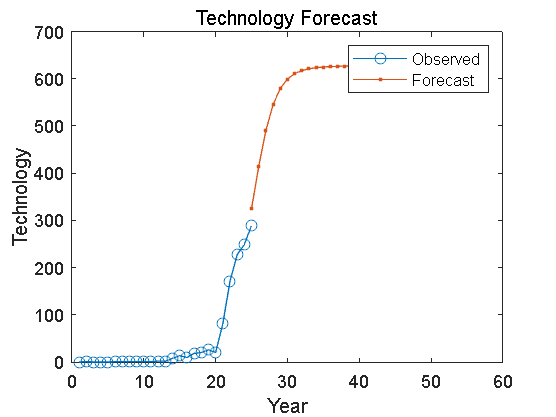

numTimeStepsTrainTechnology = numel(dataTechnology); 
dataTrainTechnology = dataTechnology(1 : numTimeStepsTrainTechnology);

% 数据标准化，零均值和单位方差
muTechnology = mean(dataTrainTechnology);
sigTechnology = std(dataTrainTechnology);
dataTrainStandardizedTechnology = (dataTrainTechnology - muTechnology) / sigTechnology;

% 训练数据
XTrainTechnology = dataTrainStandardizedTechnology(1:end-1);
YTrainTechnology = dataTrainStandardizedTechnology(2:end);

% 创建 LSTM 网络
numFeaturesTechnology= 1;
numResponsesTechnology = 1;
numHiddenUnitsTechnology = 100;

layersTechnology = [sequenceInputLayer(numFeaturesTechnology)
          lstmLayer(numHiddenUnitsTechnology)
          fullyConnectedLayer(numResponsesTechnology)
          regressionLayer];

% 设置网络参数
optionsTechnology = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.01, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Water背景下，改这个就'LearnRateDropFactor', 0.92大概会在2033碳达峰 ，0.95大概2030年...
% 训练
netTechnology = trainNetwork(XTrainTechnology, YTrainTechnology, layersTechnology, optionsTechnology);

% 预测
netTechnology = predictAndUpdateState(netTechnology, XTrainTechnology);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netTechnology, YPredTechnology] = predictAndUpdateState(netTechnology, YTrainTechnology(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictTechnology = 28;
YPredTechnology = [YPredTechnology zeros(1, numYearsToPredictTechnology - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictTechnology
    [netTechnology, YPredTechnology(:, i)] = predictAndUpdateState(netTechnology, YPredTechnology(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredTechnology = sigTechnology * YPredTechnology + muTechnology;
% 画图
figure;
plot(1:numel(dataTechnology), dataTechnology, '-o')
hold on
idx = numel(dataTechnology) : (numel(dataTechnology) + numYearsToPredictTechnology - 1);
plot(idx, YPredTechnology, '.-')
hold off 
xlabel("Year");
ylabel("Technology");
title("Technology Forecast");
legend("Observed", "Forecast");

disp(YPredTechnology)

  324.9796  413.8664  490.3602  545.1845  579.5014  599.4218  610.7194  617.1978  621.0216  623.3601  624.8419  625.8121  626.4661  626.9180  627.2372  627.4673  627.6359  627.7614  627.8561  627.9285  627.9845  628.0283  628.0629  628.0905  628.1125  628.1304  628.1450  628.1570



## 水力发电的百分占比LSTM模型

dataWaterpercent_2= dataTable.WaterPercent(1:25);
dataWaterpercent_1=dataWaterpercent_2*100;
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_1=(dataWaterpower_kilowatt / dataTotalpower_kilowatt)*100;
dataWaterpercent=dataWaterpercent_1.';
disp(dataWaterpercent);

   1.0e+04 *

    1.1084    1.1989    1.3354    1.8344    2.2196    2.2153    2.0825    2.2605    2.1335    2.2596    3.4062    3.9404    4.0088    4.1658    3.5500    5.1165    4.7780    6.8066    7.8922    7.3373    6.9991    7.1124    7.6936    8.3116    8.9051



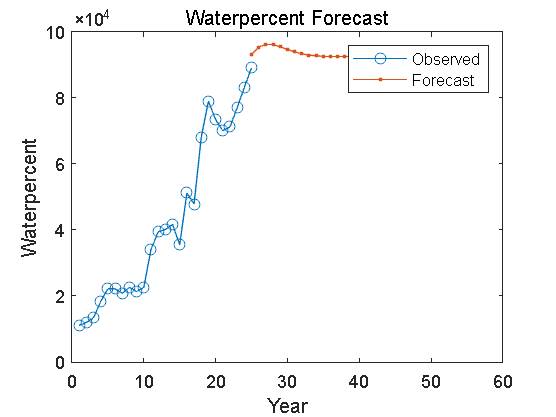


numTimeStepsTrainWaterpercent = numel(dataWaterpercent); % 使用所有的数据来训练
dataTrainWaterpercent = dataWaterpercent(1 : numTimeStepsTrainWaterpercent);

% 数据标准化，零均值和单位方差
muWaterpercent = mean(dataTrainWaterpercent);
sigWaterpercent = std(dataTrainWaterpercent);
dataTrainStandardizedWaterpercent = (dataTrainWaterpercent - muWaterpercent) / sigWaterpercent;

% 训练数据
XTrainWaterpercent = dataTrainStandardizedWaterpercent(1:end-1);
YTrainWaterpercent = dataTrainStandardizedWaterpercent(2:end);

% 创建 LSTM 网络
numFeaturesWaterpercent= 1;
numResponsesWaterpercent = 1;
numHiddenUnitsWaterpercent = 130;

layersWaterpercent = [sequenceInputLayer(numFeaturesWaterpercent)
          lstmLayer(numHiddenUnitsWaterpercent)
          fullyConnectedLayer(numResponsesWaterpercent)
          regressionLayer];

% 设置网络参数
optionsWaterpercent = trainingOptions('adam', ...
    'MaxEpochs', 550, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 50, ...
    'LearnRateDropFactor', 0.93, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

netWaterpercent = trainNetwork(XTrainWaterpercent, YTrainWaterpercent, layersWaterpercent, optionsWaterpercent);

% 预测
netWaterpercent = predictAndUpdateState(netWaterpercent, XTrainWaterpercent);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netWaterpercent, YPredWaterpercent] = predictAndUpdateState(netWaterpercent, YTrainWaterpercent(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictWaterpercent = 28;
YPredWaterpercent = [YPredWaterpercent zeros(1, numYearsToPredictWaterpercent - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictWaterpercent
    [netWaterpercent, YPredWaterpercent(:, i)] = predictAndUpdateState(netWaterpercent, YPredWaterpercent(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredWaterpercent = sigWaterpercent * YPredWaterpercent + muWaterpercent;
% 画图
figure;
plot(1:numel(dataWaterpercent), dataWaterpercent, '-o')
hold on
idx = numel(dataWaterpercent) : (numel(dataWaterpercent) + numYearsToPredictWaterpercent - 1);
plot(idx, YPredWaterpercent, '.-')
hold off 
xlabel("Year");
ylabel("Waterpercent");
title("Waterpercent Forecast");
legend("Observed", "Forecast");

disp(YPredWaterpercent)

   1.0e+04 *

    9.3017    9.5296    9.6130    9.6000    9.5363    9.4569    9.3836    9.3263    9.2873    9.2640    9.2520    9.2469    9.2450    9.2439    9.2419    9.2385    9.2336    9.2273    9.2202    9.2126    9.2048    9.1971    9.1897    9.1827    9.1761    9.1700    9.1642    9.1588



## 原始STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Guizhou_data.xlsx'; 
dataTable = readtable(filename);

dataPopulation = dataTable.Population_wan(1:25) * 1e4; % 人口
dataGDP = dataTable.Per_capita_GDP_yuan(1:25); % 人均GDP
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25); % 技术市场交易量
dataEmission = dataTable.CarbonEmissions_mt(1:25); % 碳排放量

% 创建数据矩阵
dataMatrix = [dataPopulation, dataGDP, dataTechnology, dataEmission];

% 对数转换
dataLog = log(dataMatrix + 1); % 加1是为了避免对0取对数

% 将对数转换后的数据转换为dataTable
dataTableLog = array2table(dataLog, 'VariableNames', {'LogPopulation', 'LogGDP', 'LogTechnology', 'LogEmission'});

% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 变量名
variableNames = {'Population', 'GDP', 'Technology', 'Emission'};

% 相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                  Population      GDP       Technology    Emission
                  __________    ________    __________    ________

    Population            1     0.086449      0.2885      -0.19406
    GDP            0.086449            1     0.93169       0.91221
    Technology       0.2885      0.93169           1       0.77861
    Emission       -0.19406      0.91221     0.77861             1




% 绘制热力图
%figure;
%h = heatmap(variableNames, variableNames, correlationMatrix);
%h.Title = 'Pearson Correlation Matrix Heatmap';
%h.Colormap = bone; % 颜色映射选择
%h.ColorScaling = 'scaledcolumns'; % 颜色标准化

% 拟合模型
lm_formula = 'LogEmission ~ LogPopulation + LogGDP + LogTechnology';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogEmission ~ 1 + LogPopulation + LogGDP + LogTechnology

估计系数:
                     Estimate        SE        tStat        pValue  
                     _________    ________    ________    __________

    (Intercept)         79.872      26.968      2.9618     0.0074436
    LogPopulation      -4.5642      1.5222     -2.9985     0.0068454
    LogGDP              0.6021     0.11818      5.0948    4.7932e-05
    LogTechnology    -0.051048    0.070673    -0.72232       0.47807


观测值数目: 25，误差自由度: 21
均方根误差: 0.195
R 方: 0.909，调整 R 方 0.896
F 统计量(常量模型): 70.3，p 值 = 4.06e-11


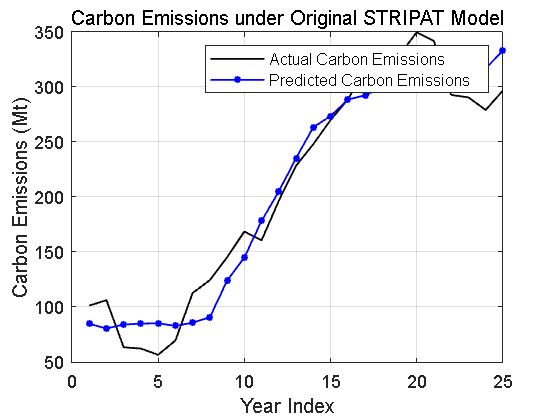


% 原始结果曲线图
figure;
plot(exp(dataTableLog.LogEmission), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Original STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 改良STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Guizhou_data.xlsx'; 
dataTable = readtable(filename);

% 数据提取与转换 重新提取一下 变原单位
dataGDP = dataTable.Per_capita_GDP_yuan(1:25);
dataPopulation = dataTable.Population_wan(1:25) * 1e4;
dataSecond = dataTable.Value_added_of_the_secondary_industry_billion(1:25) * 1e9;
dataCE = dataTable.CarbonEmissions_mt(1:25);
energyconsumption = (dataTable.Coal_consumption_10000_tons(1:25) + dataTable.Coke_consumption_10000_tons(1:25) + dataTable.Fuel_oil_consumption_10000_tons(1:25)) * 1e4;
dataNaturalgas = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25) * 1e9;
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25) * 1e8;
hydroPower = dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
totalPower = dataTable.Total_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
dataWaterPercent = (hydroPower ./ totalPower) * 100;

% 数据标准化处理
dataMatrix = [dataCE, dataGDP, dataPopulation, dataSecond, energyconsumption, dataNaturalgas, dataTechnology, dataWaterPercent];

dataLog = log(dataMatrix+1);
% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 定义变量名称
variableNames = {'CarbonEmissions', 'GDP', 'Population', 'SecondaryIndustry', 'EnergyConsumption', 'NaturalGas', 'TechnologyTransactions', 'HydroPowerPercentage'};

% 输出相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                              CarbonEmissions      GDP       Population    SecondaryIndustry    EnergyConsumption    NaturalGas    TechnologyTransactions    HydroPowerPercentage
                              _______________    ________    __________    _________________    _________________    __________    ______________________    ____________________

    CarbonEmissions                     1         0.91221     -0.19406          0.92281              0.96524          0.51992              0.86169                  -0.3362      
    GDP                           0.91221               1     0.086449          0.99878              0.87663          0.77489              0.93606                  -0.1273      
    Population                   -0.19406        0.086449            1         0.061123             -0.22863           0.5601              0.19383                  0.37167      
    SecondaryIndustry             0.92281         0.99878     0.061123                1               0.8965 

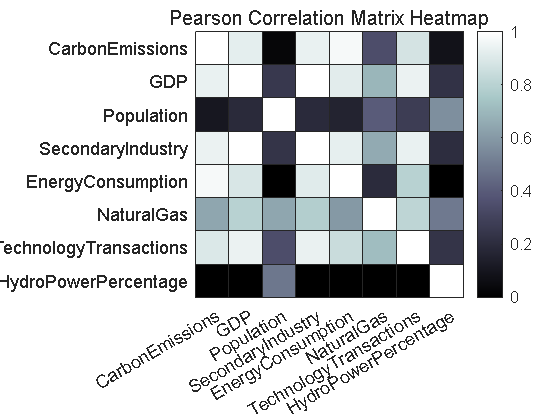


% 热力图
figure; % jet太难看了 换个颜色 winter也难看 pink不错 就bone了
%mycolor = [0.474509803921569,0.650980392156863,0.807843137254902;...
% 0.682352941176471,0.823529411764706,0.898039215686275;...
 %0.941176470588235,0.972549019607843,0.862745098039216;...
 %0.992156862745098,0.968627450980392,0.705882352941177;...
 %1,0.901960784313726,0.603921568627451];
h = heatmap(variableNames, variableNames, correlationMatrix);
h.Title = 'Pearson Correlation Matrix Heatmap';
h.Colormap = bone; 
h.ColorScaling = 'scaledcolumns'; 

%colormap(gca,mycolor);


% 创建数据表格
variableNames = {'LogCE','LogGDP', 'LogPopulation', 'LogSecond',  'LogEnergyConsumption', 'LogNaturalGas', 'LogTechnology', 'LogWaterPercent'};
dataTableLog = array2table(dataLog, 'VariableNames', variableNames);

% 拟合模型
lm_formula = 'LogCE ~ LogPopulation + LogGDP + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogCE ~ 1 + LogGDP + LogPopulation + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent

估计系数:
                            Estimate       SE        tStat       pValue  
                            ________    ________    _______    __________

    (Intercept)               48.469      18.906     2.5637      0.020134
    LogGDP                    1.4733      1.1356     1.2973       0.21185
    LogPopulation             -2.542      1.1239    -2.2618      0.037105
    LogSecond                -1.7834      1.0941    -1.6301       0.12148
    LogEnergyConsumption      1.8712     0.25867     7.2341    1.3968e-06
    LogNaturalGas           0.081706     0.12394    0.65925       0.51857
    LogTechnology           0.089419    0.022844     3.9143     0.0011165
    LogWaterPercent          0.23159     0.18519     1.2505       0.22804


观测值数目: 25，误差自由度: 17
均方根误差: 0.0854
R 方: 0.986，调整 R 方 0.98
F 统计量(常量模型): 170，p 值 = 1.8e-14


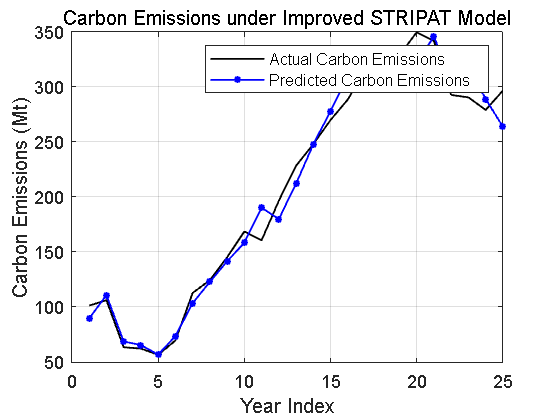


lmCoefficients = model.Coefficients.Estimate; % 存储系数
% 结果曲线图
figure;
plot(exp(dataTableLog.LogCE), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Improved STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 将预测得到的各个YPred的LSTM值带入到改良STRIPAT模型

YPredLogGDP = log(YPredGDP).';  % 取对数并转置
YPredLogPopulation = log(YPredPopulation).';
YPredLogSecond = log(YPredSecond).';
YPredLogEnergy = log(YPredEnergy).';
YPredLogNaturalGas = log(YPredNaturalgas).';
YPredLogTechnology = log(YPredTechnology).';
YPredLogWaterPercent = log(YPredWaterpercent).';
dataCE = dataTable.CarbonEmissions_mt(1:25); % 真实碳排放数据
Years = dataTable.Year(1:25); 

% 计算预测的碳排放

PredictedLogCE = lmCoefficients(1) + lmCoefficients(3) * YPredLogGDP + lmCoefficients(2) * YPredLogPopulation + ...
                 lmCoefficients(4) * YPredLogSecond + lmCoefficients(5) * YPredLogEnergy + ...
                 lmCoefficients(6) * YPredLogNaturalGas + lmCoefficients(7) * YPredLogTechnology + ...
                 lmCoefficients(8) * YPredLogWaterPercent;
% 将对数形式的预测碳排放转换回原始尺度
PredictedCE_1 = exp(PredictedLogCE);
PredictedCE = (PredictedCE_1)/1e16+250;
% 输出预测结果
disp('Predicted CarbonEmissions for future years:');

Predicted CarbonEmissions for future years:


disp(PredictedCE);

   1.0e+02 *

   2.8411 + 0.0000i
   2.7595 + 0.0000i
   2.7019 + 0.0000i
   2.6598 + 0.0000i
   2.6271 + 0.0000i
   2.6007 + 0.0000i
   2.5779 + 0.0000i
   2.5571 + 0.0000i
   2.5374 + 0.0000i
   2.5194 + 0.0000i
   2.5058 + 0.0000i
   2.5001 + 0.0000i
   2.5013 - 0.0006i
   2.5016 - 0.0007i
   2.5000 - 0.0000i
   2.5051 + 0.0000i
   2.5211 + 0.0000i
   2.5408 + 0.0000i
   2.5565 + 0.0000i
   2.5692 + 0.0000i
   2.5809 + 0.0000i
   2.5949 + 0.0000i
   2.6111 + 0.0000i
   2.6138 + 0.0000i
   2.6099 + 0.0000i
   2.6087 + 0.0000i
   2.6128 + 0.0000i
   2.6163 + 0.0000i



% 绘制实际与预测的碳排放量对比图
figure;
plot(Years, dataCE, 'k', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'Actual Carbon Emissions');
hold on;
plot(Years(1) + (25:52), PredictedCE, 'r*-', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'Predicted Carbon Emissions');

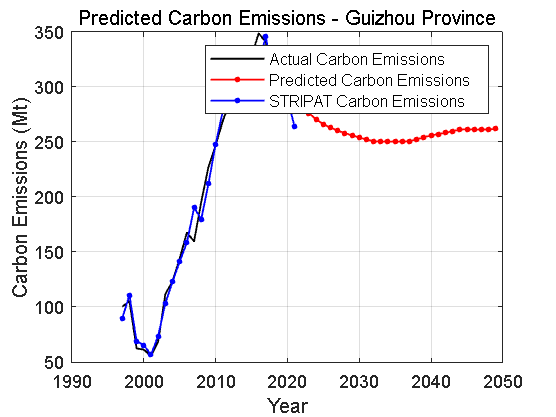

%STRIPATPred=exp(PredictedCE);
plot(Years(1)+ (0:24), exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'STRIPAT Carbon Emissions');
title('Predicted Carbon Emissions - Guizhou Province');
xlabel('Year');
ylabel('Carbon Emissions (Mt)');
legend show;
grid on;
hold off;